# AI and Robotics LAb-1

## NikhilSanjay(BL.EN.U4CSE23239)

R = rot2(45)

R =     0.5253   -0.8509
    0.8509    0.5253


R = rot2(45,'deg')

R =     0.7071   -0.7071
    0.7071    0.7071


R = rotx(45),roty(45),rotz(45)

R =     1.0000         0         0
         0    0.5253   -0.8509
         0    0.8509    0.5253


ans =     0.5253         0    0.8509
         0    1.0000         0
   -0.8509         0    0.5253


ans =     0.5253   -0.8509         0
    0.8509    0.5253         0
         0         0    1.0000


R=rotx(45,'deg')

R =     1.0000         0         0
         0    0.7071   -0.7071
         0    0.7071    0.7071


clf;
clear all;
R = rot2(45,'deg')

R =     0.7071   -0.7071
    0.7071    0.7071


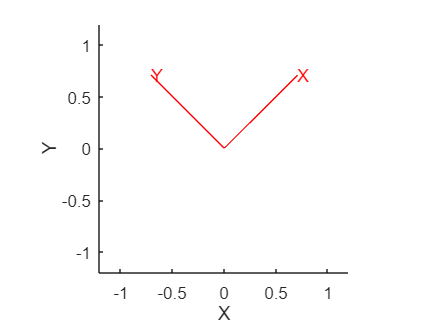

H =   Transform with properties:

    Children: [4×1 Graphics]
     Visible: on
     HitTest: on
      Matrix: [4×4 double]

  Show all properties


H=trplot2(R,'color','r')

clf;
clear all;
R = rotx(45,'deg')

R =     1.0000         0         0
         0    0.7071   -0.7071
         0    0.7071    0.7071


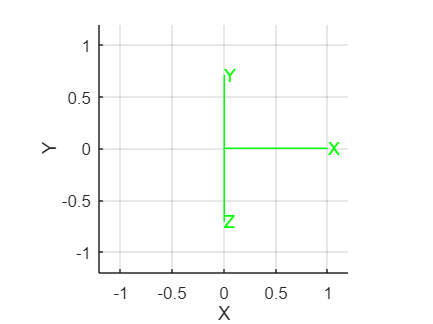

trplot(R,'color','g')

T = transl2(2,3)

T =      1     0     2
     0     1     3
     0     0     1


H = transl2(4,9) * trot2(70,'deg') 

H =     0.3420   -0.9397    4.0000
    0.9397    0.3420    9.0000
         0         0    1.0000


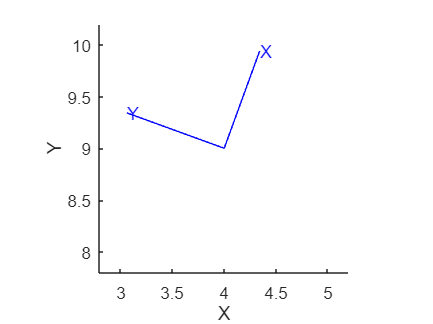

clf;
trplot2(H)

clf;
axis([-4 4 -4 4 -4 4]);     
view(3);                  
grid on;
hold on;
H1 = transl(1,2,3)*troty(45,'deg')

H1 =     0.7071         0    0.7071    1.0000
         0    1.0000         0    2.0000
   -0.7071         0    0.7071    3.0000
         0         0         0    1.0000


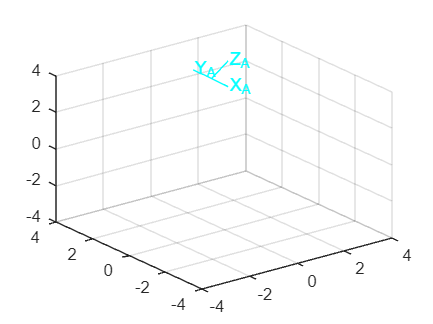

trplot(H1, 'frame', 'A', 'color', 'c');

clf;
clear all;
axis([-4 4 -4 4 -4 4]);     
view(3); 
grid on
H = transl2(4,9)*trot2(70,'deg')

H =     0.3420   -0.9397    4.0000
    0.9397    0.3420    9.0000
         0         0    1.0000


H1=eye(3)

H1 =      1     0     0
     0     1     0
     0     0     1


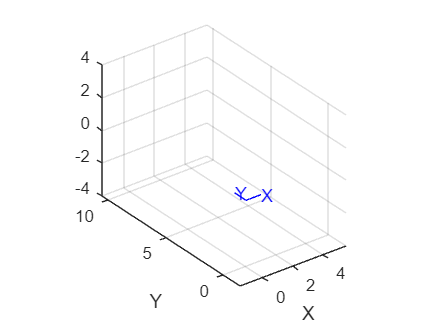

tranimate2(H,H1)

## Practice Questions

theta = 45;                      
R = trotz(theta, 'deg');        
R = R(1:3, 1:3);                 
RT_R = R' * R;                   
inverse_R = inv(R);              
det_R = det(R);                  

disp('R'' * R =');

R' * R =


disp(RT_R)

     1     0     0
     0     1     0
     0     0     1




disp('inv(R) =');

inv(R) =


disp(inverse_R)

    0.7071    0.7071         0
   -0.7071    0.7071         0
         0         0    1.0000




disp('R'' =');

R' =


disp(R')

    0.7071    0.7071         0
   -0.7071    0.7071         0
         0         0    1.0000




disp('det(R) =');

det(R) =


disp(det_R)

     1



X=rotx(90);
XY=X*roty(0);
XYX = XY*rotx(90);
compareX = rotx(180)

compareX =     1.0000         0         0
         0   -0.5985    0.8012
         0   -0.8012   -0.5985


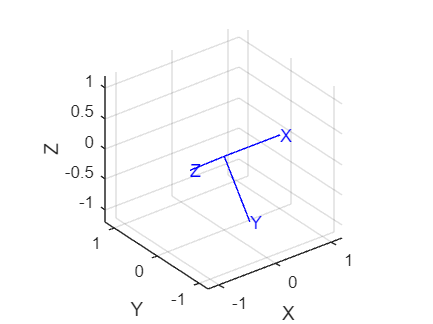


trplot(XYX)

trplot(rotx(180))

## LAB SHEET  - 2

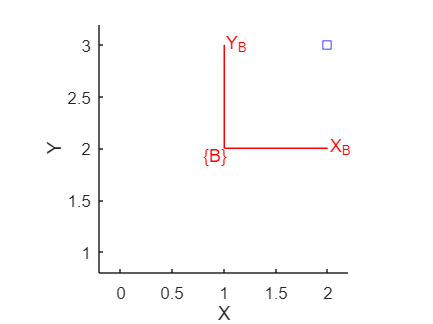

clear all;
clf;
clc;
B = transl2(1,2);
Ap=[2;3];
trplot2(B,'frame','B','color','r')
hold on
plot_point(Ap)

Pb = inv(B)*[Ap;1]

Pb =      1
     1
     1


h2e(Pb)

ans =      1
     1


Pb = h2e(inv(B)*e2h(Ap))

Pb =      1
     1


syms theta
R = rot2(theta)

$$R = \left(\begin{array}{cc} \cos\left(\theta \right) & -\sin\left(\theta \right)\\ \sin\left(\theta \right) & \cos\left(\theta \right) \end{array}\right)$$

simplify(R*R)

$$ans = \left(\begin{array}{cc} \cos\left(2\,\theta \right) & -\sin\left(2\,\theta \right)\\ \sin\left(2\,\theta \right) & \cos\left(2\,\theta \right) \end{array}\right)$$

R = eul2r(0.1,0.2,0.3)

R =     0.9021   -0.3836    0.1977
    0.3875    0.9216    0.0198
   -0.1898    0.0587    0.9801


EU = eul2r(0.1,-0.2,0.3)

EU =     0.9021   -0.3836   -0.1977
    0.3875    0.9216   -0.0198
    0.1898   -0.0587    0.9801


EU2 = eul2tr(EU)

EU2 = EU2(:,:,1) =

    0.7178   -0.6565   -0.2320         0
    0.5917    0.7508   -0.2936         0
    0.3669    0.0735    0.9273         0
         0         0         0    1.0000


EU2(:,:,2) =

    0.5671   -0.3667    0.7375         0
    0.2100    0.9302    0.3010         0
   -0.7964   -0.0158    0.6045         0
         0         0         0    1.0000


EU2(:,:,3) =

    0.3893   -0.9193   -0.0576         0
    0.9205    0.3905   -0.0111         0
    0.0327   -0.0487    0.9983         0
         0         0         0    1.0000


R1 = eul2r(EU)

R1 = R1(:,:,1) =

    0.7178   -0.6565   -0.2320
    0.5917    0.7508   -0.2936
    0.3669    0.0735    0.9273


R1(:,:,2) =

    0.5671   -0.3667    0.7375
    0.2100    0.9302    0.3010
   -0.7964   -0.0158    0.6045


R1(:,:,3) =

    0.3893   -0.9193   -0.0576
    0.9205    0.3905   -0.0111
    0.0327   -0.0487    0.9983


## PRACTICE QUESTION

H = transl(1,4,8)

H =      1     0     0     1
     0     1     0     4
     0     0     1     8
     0     0     0     1


H = H* trotx(45,'deg')*troty(70,'deg')*trotz(30,'deg')

H =     0.2962   -0.1710    0.9397    1.0000
    0.9290    0.2801   -0.2418    4.0000
   -0.2219    0.9446    0.2418    8.0000
         0         0         0    1.0000


eulerAngles = tr2eul(H)

eulerAngles =    -0.2519    1.3265    1.3401


AngelVector = tr2angvec(H)

AngelVector = 1.6618

RPY = tr2rpy(H)

RPY =     1.3202    0.2238    1.2621
